We create a simulink system where we input a sin function, pass it through a 1-D Lookup table and get some output

Our aim is to use a fuzzy logic controller to bring the changed output back to the original

out=sim('testing')

Simulation

Input

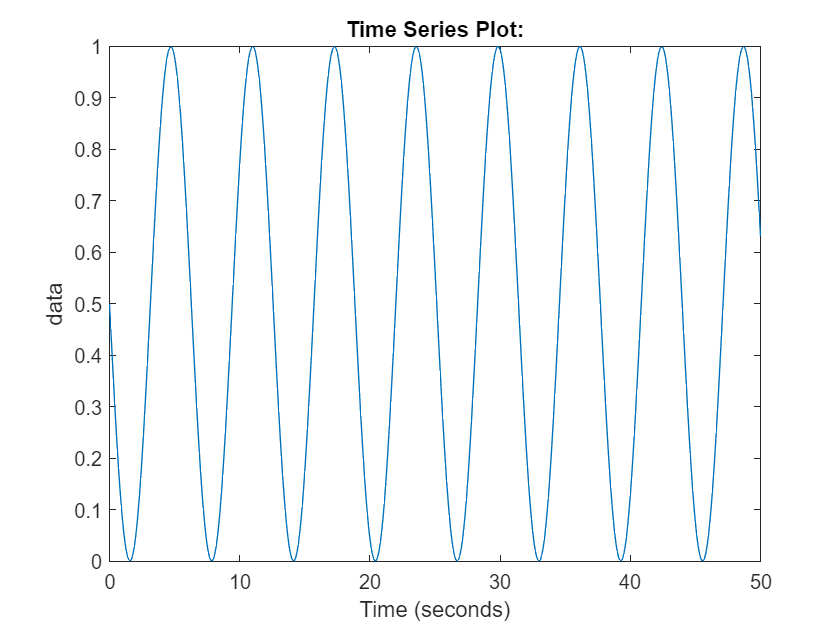

plot(out.u)

Output

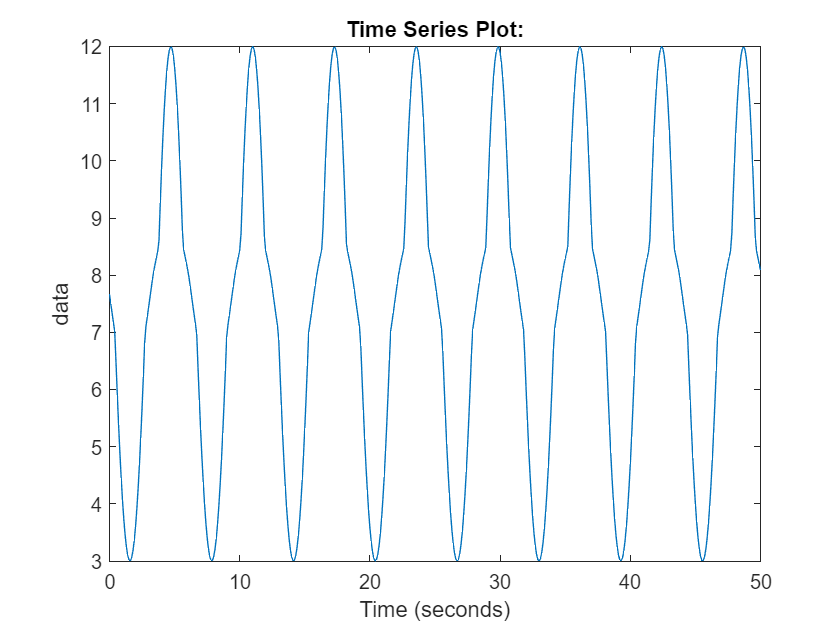

plot(out.y)

System below uses a fuzzy logic controller to chage the output of Lookup Table back to the input signal

We do that by feeding output y as input and input u as output into the anfis and training it for 300 epochs

Below we see output of a fuzzy controler given input from Lookup table

This fuzzy controller uses 5 membership functions of type trimf

We obsereve very good representation

out2=sim('testing2.slx')

for 5 mf trimf

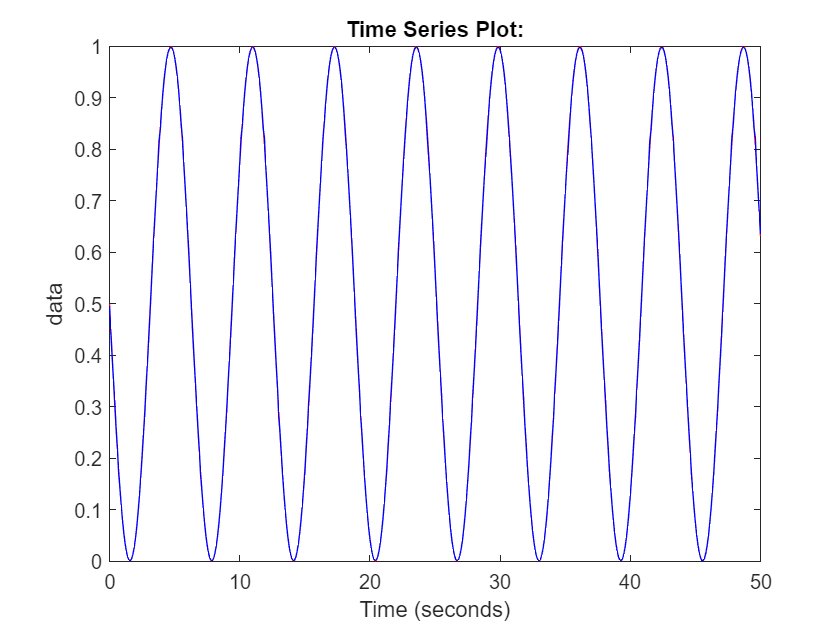

plot(out2.u1,'r');hold on;
plot(out2.y1,'b');hold off;

This is the same system as before exept a different mf type

This fuzzy controller uses 5 membership functions of type gauss2mf

We again see very good representation

out3=sim('testing3')

for 5 mf gauss2mf

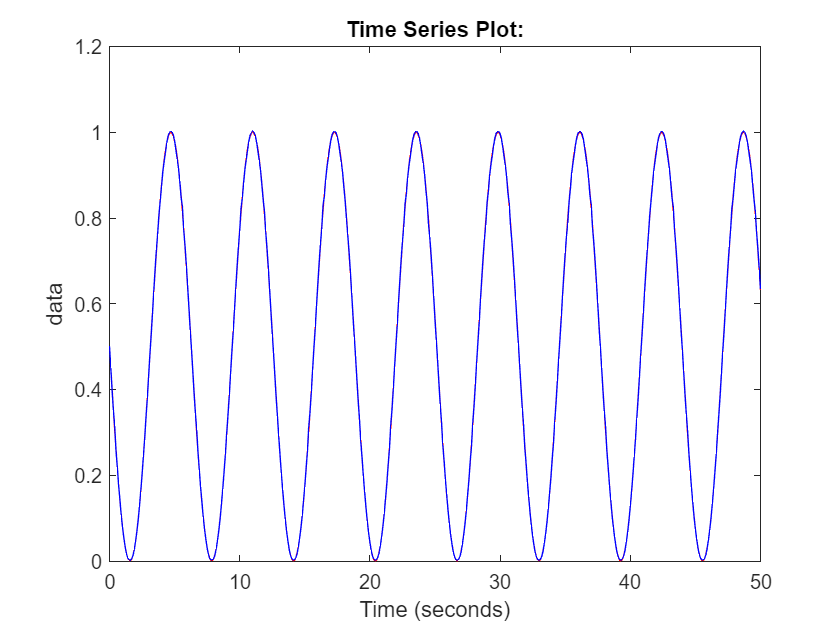

plot(out3.u1,'r');hold on
plot(out3.y1,'b');hold off

Below we changed the system to only use 2 mf

For 2 mf of type trimf

We observe poor representation especially at minimas and maximas

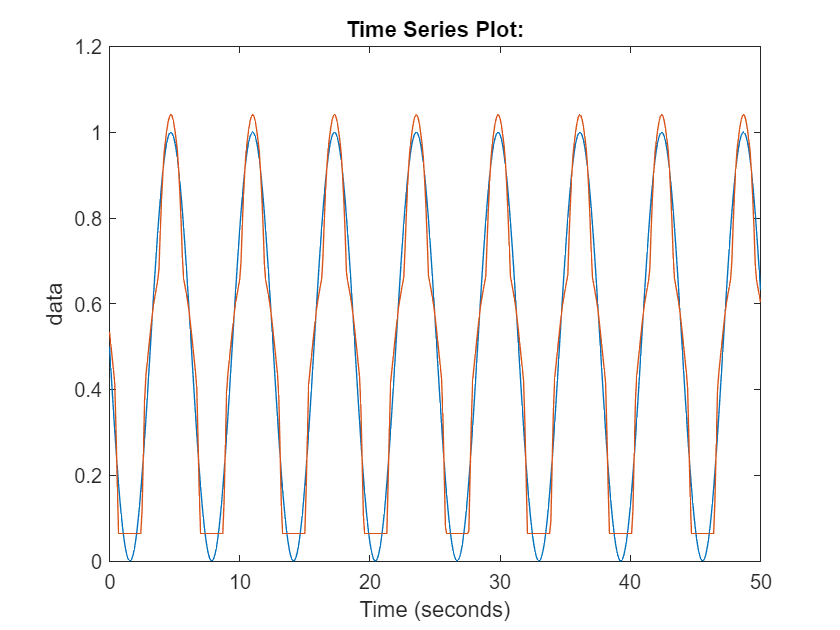

out4=sim("testing4.slx")
plot(out4.u1);hold on
plot(out4.y1);hold off

For 2 mf of gauss2mf

We observe poor representation especially in maximas where minimas are close to desired output

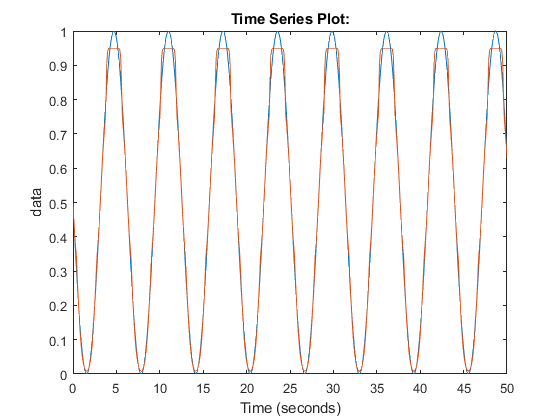

out5=sim("testing5.slx")
plot(out5.u1);hold on
plot(out5.y1);hold off

ERROR of each FIS system

For 2 mf trimf:

error=erfunc(out4.u1.DATA,out4.y1.DATA)

error = 1.8731

Mean_absolute_error=mae(out4.u1.DATA,out4.y1.DATA)

Mean_absolute_error = 0.0514

For 5 mf trimf

error1=erfunc(out2.u1.DATA,out2.y1.DATA)

error1 = 0.0044

Mean_absolute_error1=mae(out2.u1.DATA,out2.y1.DATA)

Mean_absolute_error1 = 0.0020

For 2 mf gauss2mf

error2=erfunc(out5.u1.DATA,out5.y1.DATA)

error2 = 0.3099

Mean_absolute_error2=mae(out5.u1.DATA,out5.y1.DATA)

Mean_absolute_error2 = 0.0175

5 mf gauss2mf

error3=erfunc(out3.u1.DATA,out3.y1.DATA)

error3 = 0.0045

Mean_absolute_error3=mae(out3.u1.DATA,out3.y1.DATA)

Mean_absolute_error3 = 0.0023

Sum of squared difference of each array entry e=(x-y)^2

function error=erfunc(x,y)
error=ones(1,length(x))*(x-y).^2;
end
